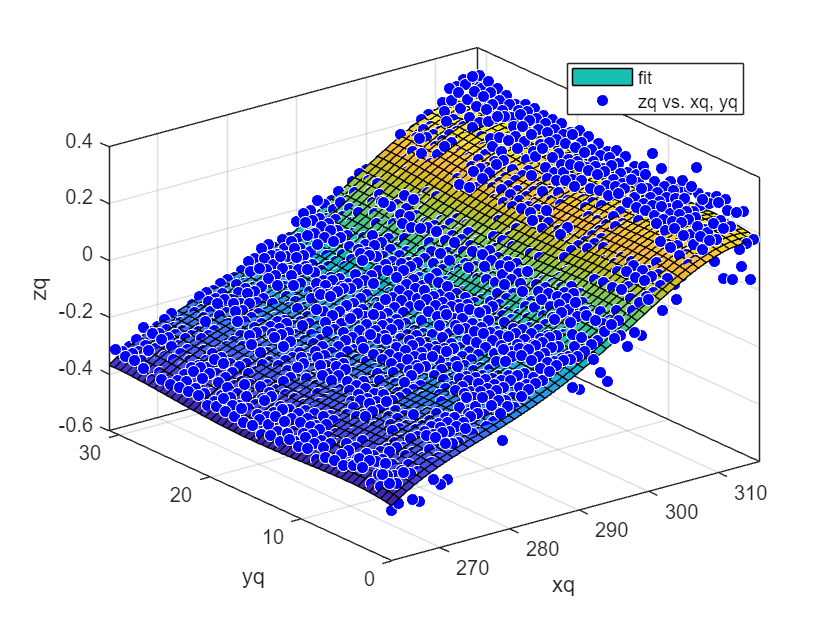

iidx = xq > 0;
X = xq(iidx); Y = yq(iidx); Z = zq(iidx);
d=1;
[X,Y,Z] = PreprocessDate([X,Y,Z],d);
n = 4;%拟合方程次数
[f  gof] = createFit(X, Y, Z, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

-2198.4758 + -0.31297*Y + 0.0016184*Y*Y + 4.0322e-05*Y*Y*Y + -7.4697e-07*Y*Y*Y*Y + 0.0031043*X*Y + -1.6999e-05*X*Y*Y + 3.8624e-08*X*Y*Y*Y + -1.0034e-05*X*X*Y + 2.6339e-08*X*X*Y*Y + 1.0854e-08*X*X*X*Y + -3.2599e-07*X*X*X*X 


disp(gof)

           sse: 1.9698
       rsquare: 0.9667
           dfe: 1653
    adjrsquare: 0.9664
          rmse: 0.0345



%保存拟合结果到文本
% c2 = cell2mat(struct2cell(gof));
% a = {s;c2};
% fileID = fopen(strcat(fileparts(filepath),'poly.txt'),'w');%%fileparts提取文件路径
% formatSpec = '%s %d %2.1f %s\n';
% [nrows,ncols] = size(a);
% for row = 1:nrows
%     fprintf(fileID,formatSpec,a{row,:}); % 注意此处不用{}，而是（）时，得到的字符串有引号，需注意
% end
% fclose(fileID);
